%% APARTADO (a) – Análisis CELP con extras y SNR (LPC y CELP)
% - Recorre K={64,256,1024}, M={10,12,16}, c={0.60,0.75,0.90}
% - Solo ANÁLISIS (usa celpana); NO exporta audio.
% - Calcula: voiced/unvoiced, IS/LSD, |θ0| y RMS(θ0), F0 medio, y AHORA:
%             SNR_LPC (por residuo) y SNR_CELP (analysis-by-synthesis).
% - Gráficas: Boxplot SNR_CELP vs K, Heatmap SNR_CELP(M,K | c=0.75),
%             SNR_CELP vs c por K.

clc; clear; close all;

% ---------------- Parámetros base ----------------
Fs_target = 8000;          % Hz
N  = 160;                  % 20 ms
L  = 40;                   % 5 ms
Pidx = [16 160];           % pitch lag (2–20 ms)
rng(0);                    % reproducibilidad
nfft_spec = 512;           % para métricas espectrales

% ---------------- Archivos de audio ----------------
wav_list = { 'frase.wav', 'e.wav', 'r.wav', 'z.wav', 'we were away a year ago_lrr.wav' };
wav_list = wav_list(cellfun(@isfile, wav_list));
assert(~isempty(wav_list), 'No se encontraron .wav en la carpeta.');

% ---------------- Barridos (>=3 por parámetro) ----------------
M_list = [10 12 16];
c_list = [0.60 0.75 0.90];
CB_defs = { ...
    struct('name','gauss64',   'type','gaussian','K',64),   ...
    struct('name','gauss256',  'type','gaussian','K',256),  ...
    struct('name','gauss1024', 'type','gaussian','K',1024), ...
    struct('name','2pulses256','type','2pulses','K',256)    ... % extra algebraico
};

% ---------------- Bucle principal ----------------
results = table();
case_id = 0;

fprintf('\n=== APARTADO (a): Análisis CELP (SNR incluido) ===\n');


=== APARTADO (a): Análisis CELP (SNR incluido) ===


fprintf('Fs=%d Hz, N=%d, L=%d, pitch-lag=[%d,%d]\n\n', Fs_target, N, L, Pidx(1), Pidx(2));

Fs=8000 Hz, N=160, L=40, pitch-lag=[16,160]




for icb = 1:numel(CB_defs)
    CB = CB_defs{icb};
    cb = make_codebook(L, CB.type, CB.K);   % L x K

    for im = 1:numel(M_list)
        M = M_list(im);
        for ic = 1:numel(c_list)
            c = c_list(ic);
            case_id = case_id + 1;

            % --- Ejecuta análisis para TODOS los wavs y agrega estadísticas ---
            all_stats = [];
            for iw = 1:numel(wav_list)
                fname = wav_list{iw};
                [x,Fs] = audioread(fname);
                x = x(:,1); % mono

                if Fs ~= Fs_target
                    x = resample(x, Fs_target, Fs);
                    Fs = Fs_target;
                end
                x = x / (max(abs(x))+eps);

                stats = run_celp_analysis_case(x, N, L, M, c, cb, Pidx, nfft_spec);
                stats.file = string(fname);
                all_stats = [all_stats; stats]; %#ok<AGROW>
            end

            % --- Resumen por "caso" (promedios a través de todos los wavs) ---
            avg_k_norm          = mean([all_stats.k_norm]);
            avg_theta0          = mean([all_stats.theta0_mean]);
            avg_theta0_abs      = mean([all_stats.theta0_abs_mean]);
            avg_theta0_rms      = mean([all_stats.theta0_rms]);
            avg_P               = mean([all_stats.P_mean]);
            avg_b               = mean([all_stats.b_mean]);
            avg_b_voiced        = mean([all_stats.b_voiced_mean]);
            avg_b_unvoiced      = mean([all_stats.b_unvoiced_mean]);
            avg_P_voiced        = mean([all_stats.P_voiced_mean]);
            avg_IS              = mean([all_stats.IS_mean]);
            avg_LSD             = mean([all_stats.LSD_mean]);
            avg_SNR_LPC         = mean([all_stats.SNR_LPC_dB]);
            avg_SNR_CELP        = mean([all_stats.SNR_CELP_dB]);
            % Bootstrap CI (promediamos los límites de cada wav; opción rápida)
            avg_b_v_lo          = mean([all_stats.b_voiced_ci_lo]);
            avg_b_v_hi          = mean([all_stats.b_voiced_ci_hi]);
            tot_time            = sum([all_stats.time_s]);
            F0_mean_Hz          = Fs_target / max(avg_P, eps);

            row = table( ...
                uint32(case_id), string(CB.name), string(CB.type), uint32(CB.K), uint32(M), c, ...
                avg_k_norm, avg_theta0, avg_theta0_abs, avg_theta0_rms, ...
                avg_P, F0_mean_Hz, avg_b, avg_b_voiced, avg_b_unvoiced, avg_P_voiced, ...
                avg_IS, avg_LSD, avg_SNR_LPC, avg_SNR_CELP, ...
                avg_b_v_lo, avg_b_v_hi, tot_time, ...
                'VariableNames', { ...
                    'case_id','codebook','cb_type','K','M','c', ...
                    'k_norm','theta0_mean','theta0_abs_mean','theta0_rms', ...
                    'P_mean','F0_mean_Hz','b_mean','b_voiced_mean','b_unvoiced_mean','P_voiced_mean', ...
                    'IS_mean','LSD_mean','SNR_LPC_dB','SNR_CELP_dB', ...
                    'b_voiced_ci_lo','b_voiced_ci_hi','proc_time_s' ...
                });
            results = [results; row]; %#ok<AGROW>

            fprintf(['[Caso %02d] CB=%-12s(K=%4d)  M=%2d  c=%.2f  -->  ', ...
                     '<k_norm>=%.2f, <|θ0|>=%.3f, RMS(θ0)=%.3f, ', ...
                     'SNR_LPC=%.1f dB, SNR_CELP=%.1f dB, ', ...
                     '<P>=%.1f (F0≈%.1f Hz), <b>=%.3f, bV=%.3f [%.3f,%.3f], bU=%.3f, ', ...
                     'IS=%.3f, LSD=%.3f dB  (t=%.1fs)\n'], ...
                    case_id, CB.name, CB.K, M, c, ...
                    avg_k_norm, avg_theta0_abs, avg_theta0_rms, ...
                    avg_SNR_LPC, avg_SNR_CELP, ...
                    avg_P, F0_mean_Hz, avg_b, avg_b_voiced, avg_b_v_lo, avg_b_v_hi, avg_b_unvoiced, ...
                    avg_IS, avg_LSD, tot_time);
        end
    end
end

[Caso 01] CB=gauss64     (K=  64)  M=10  c=0.60  -->  <k_norm>=0.49, <|θ0|>=0.027, RMS(θ0)=0.050, SNR_LPC=14.1 dB, SNR_CELP=4.9 dB, <P>=85.5 (F0≈93.5 Hz), <b>=0.828, bV=0.892 [0.806,0.973], bU=0.808, IS=13.339, LSD=63.345 dB  (t=1.8s)
[Caso 02] CB=gauss64     (K=  64)  M=10  c=0.75  -->  <k_norm>=0.48, <|θ0|>=0.029, RMS(θ0)=0.060, SNR_LPC=14.1 dB, SNR_CELP=5.7 dB, <P>=85.8 (F0≈93.2 Hz), <b>=0.829, bV=0.871 [0.786,0.952], bU=0.810, IS=13.339, LSD=63.345 dB  (t=1.6s)
[Caso 03] CB=gauss64     (K=  64)  M=10  c=0.90  -->  <k_norm>=0.49, <|θ0|>=0.030, RMS(θ0)=0.064, SNR_LPC=14.1 dB, SNR_CELP=6.4 dB, <P>=85.0 (F0≈94.1 Hz), <b>=0.827, bV=0.897 [0.817,0.978], bU=0.802, IS=13.339, LSD=63.345 dB  (t=1.6s)
[Caso 04] CB=gauss64     (K=  64)  M=12  c=0.60  -->  <k_norm>=0.49, <|θ0|>=0.027, RMS(θ0)=0.051, SNR_LPC=14.2 dB, SNR_CELP=4.9 dB, <P>=85.4 (F0≈93.7 Hz), <b>=0.824, bV=0.892 [0.803,0.980], bU=0.802, IS=13.337, LSD=63.340 dB  (t=1.6s)
[Caso 05] CB=gauss64     (K=  64)  M=12  c=0.75  -->  <k_nor


% ---------------- Guardado ----------------
writetable(results, 'aparta_a_resultados_SNR.csv');
save('aparta_a_resultados_SNR.mat', 'results');

disp('Primeras filas de resultados:');

Primeras filas de resultados:


disp(results(1:min(size(results,1),10), :));

    case_id     codebook      cb_type       K     M      c      k_norm     theta0_mean    theta0_abs_mean    theta0_rms    P_mean    F0_mean_Hz    b_mean     b_voiced_mean    b_unvoiced_mean    P_voiced_mean    IS_mean    LSD_mean    SNR_LPC_dB    SNR_CELP_dB    b_voiced_ci_lo    b_voiced_ci_hi    proc_time_s
    _______    __________    __________    ___    __    ____    _______    ___________    _______________    __________    

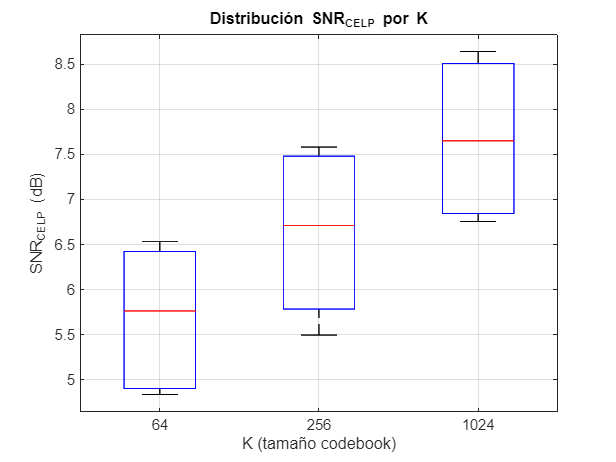


% ---------------- Gráficas SNR ----------------
% (1) Boxplot SNR_CELP vs K
figure; 
Ks = unique(results.K);
grp = []; vals = [];
for j=1:numel(Ks)
    idx = results.K == Ks(j);
    grp  = [grp;  j*ones(sum(idx),1)]; %#ok<AGROW>
    vals = [vals; results.SNR_CELP_dB(idx)]; %#ok<AGROW>
end
boxplot(vals, grp, 'Labels', string(Ks));
grid on; ylabel('SNR_{CELP} (dB)'); xlabel('K (tamaño codebook)');
title('Distribución SNR_{CELP} por K');

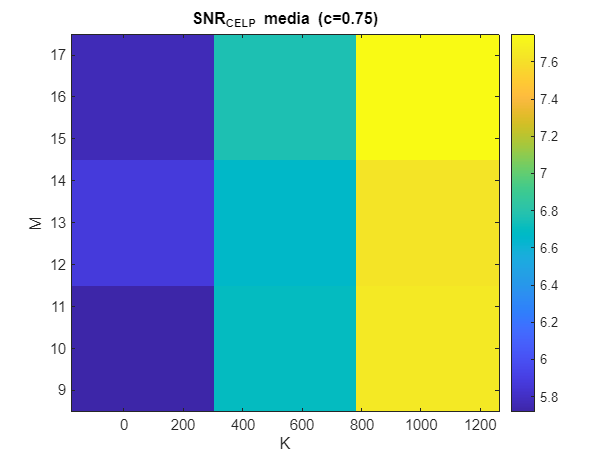


% (2) Heatmap SNR_CELP vs (M,K) para c=0.75
figure; 
c0 = 0.75; tol = 1e-6;
sel = abs(results.c - c0) < tol;
Ms = unique(results.M(sel)); Ks2 = unique(results.K(sel));
A  = nan(numel(Ms), numel(Ks2));
for i=1:numel(Ms)
  for j=1:numel(Ks2)
    idx = sel & results.M==Ms(i) & results.K==Ks2(j);
    if any(idx), A(i,j) = mean(results.SNR_CELP_dB(idx)); end
  end
end
imagesc(Ks2, Ms, A); axis xy; colorbar;
xlabel('K'); ylabel('M'); title(sprintf('SNR_{CELP} media (c=%.2f)', c0));

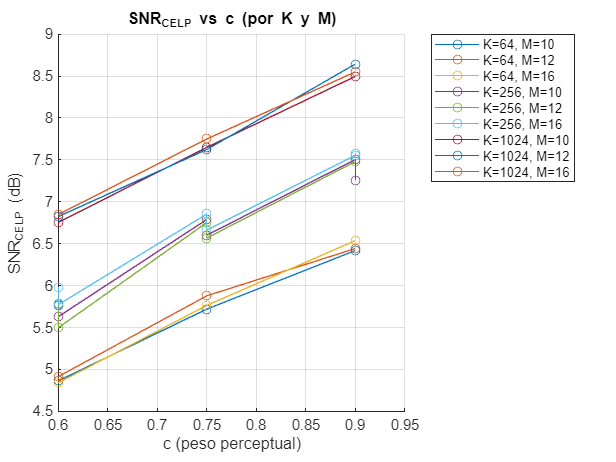


% (3) Curvas SNR_CELP vs c separadas por K
figure; hold on; grid on;
Ks3 = unique(results.K); Ms3 = unique(results.M);
for j=1:numel(Ks3)
    idx = results.K==Ks3(j);
    % Promedia sobre M para cada c (o traza por M si prefieres)
    for ii=1:numel(Ms3)
        selKM = idx & results.M==Ms3(ii);
        if any(selKM)
            [cvals, ord] = sort(results.c(selKM));
            snrvals = results.SNR_CELP_dB(selKM);
            plot(cvals, snrvals(ord), '-o', 'DisplayName', sprintf('K=%d, M=%d', Ks3(j), Ms3(ii)));
        end
    end
end
xlabel('c (peso perceptual)'); ylabel('SNR_{CELP} (dB)');
title('SNR_{CELP} vs c (por K y M)');
legend('Location','bestoutside');


%% =================== Funciones auxiliares (locales) ===================

function stats = run_celp_analysis_case(x, N, L, M, c, cb, Pidx, nfft_spec)
% Devuelve stats: uso de CB, θ0, pitch (P/F0), b, V/UV, IS/LSD
% y AHORA SNR_LPC y SNR_CELP (analysis-by-synthesis en el análisis).

F     = Pidx(2);        % tamaño de buffer de e(n)
ebuf  = zeros(F,1);
Zf    = zeros(M,1);     % estado del filtro 1/A(z/c)
Zw    = zeros(M,1);
bbuf  = 0;              % b inicial

% Estados para síntesis CELP de referencia por trama (analysis-by-synthesis)
ebuf2 = zeros(F,1);     
Zi    = zeros(M,1);

T = floor(length(x)/N); % nº de tramas completas
k_all = []; theta0_all = []; P_all = []; b_all = [];
vu_all = [];            % etiquetas voiced/unvoiced por subtrama
IS_all = []; LSD_all = [];
snr_lpc_frames  = zeros(T,1);
snr_celp_frames = zeros(T,1);

tic;
for t = 1:T
    idx = (t-1)*N + (1:N);
    xfrm = x(idx);

    % Sonoridad por trama
    vu = safe_voiunvoi(xfrm);

    % LPC del frame y residuo (para SNR_LPC)
    [ar, ~, ~, ehat] = lpcana(xfrm, M);
    num = sum(xfrm.^2) + 1e-12; den = sum(ehat.^2) + 1e-12;
    snr_lpc_frames(t) = 10*log10(num/den);

    % Métricas espectrales LPC vs señal
    [IS, LSD] = spec_metrics_from_lpc(xfrm, ar, nfft_spec);
    IS_all  = [IS_all;  IS];
    LSD_all = [LSD_all; LSD];

    % Análisis CELP (parámetros por subtramas)
    [kappa, k, theta0, P, b, ebuf, Zf, Zw] = celpana(xfrm, L, M, c, cb, Pidx, bbuf, ebuf, Zf, Zw); %#ok<ASGLU>

    % SÍNTESIS CELP del frame para SNR_CELP (analysis-by-synthesis)
    [xhat, ebuf2, Zi] = celpsyn(cb, kappa, k, theta0, P, b, ebuf2, Zi);
    xhat = xhat(:);
    xfrm = xfrm(:);
    len = min(length(xhat), length(xfrm)); % seguridad
    err = xfrm(1:len) - xhat(1:len);
    snr_celp_frames(t) = 10*log10( (sum(xfrm(1:len).^2)+1e-12) / (sum(err.^2)+1e-12) );

    % Acumulaciones
    k_all      = [k_all; k(:)];           
    theta0_all = [theta0_all; theta0(:)];
    P_all      = [P_all; P(:)];           
    b_all      = [b_all; b(:)];           
    vu_all     = [vu_all; repmat(vu, numel(k), 1)];

    bbuf = b(end); % arrastre
end
elapsed = toc;

% Métricas globales
stats.k_norm           = mean(abs(k_all)) / size(cb,2);
stats.theta0_mean      = mean(theta0_all);                 
stats.theta0_abs_mean  = mean(abs(theta0_all));            
stats.theta0_rms       = sqrt(mean(theta0_all.^2));        
stats.P_mean           = mean(P_all);
stats.b_mean           = mean(b_all);
stats.time_s           = elapsed;
stats.IS_mean          = mean(IS_all);
stats.LSD_mean         = mean(LSD_all);
stats.SNR_LPC_dB       = mean(snr_lpc_frames);
stats.SNR_CELP_dB      = mean(snr_celp_frames);

% Voiced / Unvoiced
v_sel = (vu_all == 1); u_sel = (vu_all == 0);
if any(v_sel)
    stats.b_voiced_mean = mean(b_all(v_sel));
    stats.P_voiced_mean = mean(P_all(v_sel));
    % Bootstrap CI 95% para b_voiced_mean
    [~, lo, hi] = boot_mean_ci(b_all(v_sel), 1000);
    stats.b_voiced_ci_lo = lo; stats.b_voiced_ci_hi = hi;
else
    stats.b_voiced_mean = NaN; stats.P_voiced_mean = NaN;
    stats.b_voiced_ci_lo = NaN; stats.b_voiced_ci_hi = NaN;
end
if any(u_sel)
    stats.b_unvoiced_mean = mean(b_all(u_sel));
else
    stats.b_unvoiced_mean = NaN;
end
end

function cb = make_codebook(L, type, K)
% Construye un codebook LxK.
switch lower(type)
    case 'gaussian'
        cb = randn(L, K);
        cb = cb ./ max(vecnorm(cb), eps); % normaliza columnas (energía unitaria)
    case '1pulse' % ejemplo algebraico: una delta por columna
        pos = round(linspace(1, L, K));
        cb  = zeros(L, K);
        for i=1:K, cb(pos(i), i) = 1; end
    case '2pulses' % algebraico sencillo: 2 impulsos con signo aleatorio
        cb = zeros(L, K);
        for i=1:K
            p = randi(L, [2,1]); s = sign(randn(2,1)); s(s==0)=1;
            cb(p(1), i) = s(1); cb(p(2), i) = s(2);
        end
        cb = cb ./ max(vecnorm(cb), eps);
    otherwise
        error('Tipo de codebook no soportado: %s', type);
end
end

function v = safe_voiunvoi(xfrm)
% Intenta usar voiunvoi.m del material; si falla, usa un VAD simple por energía/ZCR.
v = 1;
try
    v = voiunvoi(xfrm);        % se espera 1 o 0
    v = double(v~=0);
catch
    % fallback simple: energía alta y ZCR baja -> voiced
    E = mean(xfrm.^2);
    Z = mean(abs(diff(sign(xfrm + 1e-12))))/2; % cruces por muestra aprox
    v = double( (E > 0.005) & (Z < 0.15) );
end
end

function [IS, LSD] = spec_metrics_from_lpc(xfrm, ar, nfft)
% ar = [1 -a1 ... -aM]; métricas espectrales del modelo LPC vs señal
% Fuerza tamaños compatibles (nfft/2+1) para Px y Ph.

nfft = double(nfft);
Nh = floor(nfft/2) + 1;    % puntos one-sided (incluye DC y Nyquist)

% --- Espectro de la señal (one-sided) ---
try
    % pwelch one-sided -> Nh puntos
    [Px,~] = pwelch(xfrm, hamming(length(xfrm)), 0, nfft, 1, 'onesided');
    Px = Px(:);
catch
    % Fallback: periodograma simple (one-sided)
    X  = fft(xfrm .* hamming(length(xfrm)), nfft);
    P2 = (abs(X).^2) / max(length(xfrm),1);  % two-sided
    % convertir a one-sided manteniendo DC y Nyquist
    P1 = P2(1:Nh);
    if mod(nfft,2)==0 && nfft>=2
        P1(2:end-1) = 2*P1(2:end-1);        % duplica energía bandas positivas (sin DC/Nyquist)
    else
        P1(2:end)   = 2*P1(2:end);
    end
    Px = P1(:);
end

% --- Espectro del modelo LPC (one-sided) ---
% freqz(b,a,n) devuelve 0..pi con 'n' puntos (half-range), pedimos nfft
% y recortamos a Nh para igualar a Px de pwelch.
[Hw,~] = freqz(1, ar, nfft);   % 0..pi (nfft puntos)
Ph = abs(Hw).^2;
Ph = Ph(1:Nh);
Ph = Ph(:);

% --- Alineación defensiva ---
L = min(numel(Px), numel(Ph));
Px = Px(1:L) + 1e-12;
Ph = Ph(1:L) + 1e-12;

% --- Métricas ---
r   = Px ./ Ph;
IS  = mean( r - log(r) - 1 );                           % Itakura–Saito
LSD = sqrt( mean( (10*log10(Px) - 10*log10(Ph)).^2 ) ); % Log-spectral distance (dB)
end

function [m, lo, hi] = boot_mean_ci(x, B)
% Bootstrap simple para media con IC 95%.
if nargin<2, B=1000; end
x = x(:); x = x(isfinite(x));
n = numel(x);
if n==0
    m = NaN; lo = NaN; hi = NaN; return;
end
m = mean(x);
boot = zeros(B,1);
for b=1:B
    idx = randi(n, n, 1);
    boot(b) = mean(x(idx));
end
lo = quantile(boot, 0.025); hi = quantile(boot, 0.975);
end


%% APARTADO (b) – Síntesis CELP y errores por caso
% Recorre los mismos barridos que (a), sintetiza y calcula errores.
% Requisitos en el path: celpana.m, celpexcit.m, celpsyn.m, lpcana.m,
% lpcweight.m, durbin.m, rf2lpc.m, voiunvoi.m (opcional), y .wav de prueba.

clc; close all;

% ---------------- Parámetros base (iguales que en (a)) ----------------
Fs_target = 8000;          % Hz
N  = 160;                  % 20 ms
L  = 40;                   % 5 ms
Pidx = [16 160];           % pitch lag (2–20 ms)
rng(0);

% ---------------- Archivos de audio ----------------
wav_list = { 'frase.wav', 'e.wav', 'r.wav', 'z.wav', 'we were away a year ago_lrr.wav' };
wav_list = wav_list(cellfun(@isfile, wav_list));
assert(~isempty(wav_list), 'No se encontraron .wav en la carpeta.');

% ---------------- Barridos (idénticos a (a)) ----------------
M_list = [10 12 16];
c_list = [0.60 0.75 0.90];
CB_defs = { ...
    struct('name','gauss64',   'type','gaussian','K',64),   ...
    struct('name','gauss256',  'type','gaussian','K',256),  ...
    struct('name','gauss1024', 'type','gaussian','K',1024), ...
    struct('name','2pulses256','type','2pulses','K',256)    ...
};

% Guardar WAV sintetizados (cuidado: genera muchos archivos)
SAVE_WAVS = false;

% ---------------- Resultados ----------------
results_b = table();
results_b_wav = table();   % detalle por wav
case_id = 0;

fprintf('\n=== APARTADO (b): Síntesis y errores ===\n');


=== APARTADO (b): Síntesis y errores ===



for icb = 1:numel(CB_defs)
    CB = CB_defs{icb};
    cb = make_codebook(L, CB.type, CB.K);   % L x K

    for im = 1:numel(M_list)
        M = M_list(im);
        for ic = 1:numel(c_list)
            c = c_list(ic);
            case_id = case_id + 1;

            % ---------------- Síntesis por cada WAV ----------------
            snr_global_vec = []; segsnr_vec = []; mse_vec = [];
            pesq_vec = []; stoi_vec = [];
            for iw = 1:numel(wav_list)
                fname = wav_list{iw};
                [x,Fs] = audioread(fname);
                x = x(:,1); % mono
                if Fs ~= Fs_target
                    x = resample(x, Fs_target, Fs);
                end
                x = x / (max(abs(x))+eps);
                xlen = numel(x);

                % Buffers de análisis (igual que en (a))
                F     = Pidx(2);
                ebuf  = zeros(F,1);
                Zf    = zeros(M,1);
                Zw    = zeros(M,1);
                bbuf  = 0;

                % Buffers de síntesis persistentes a nivel de frame
                ebuf2 = zeros(F,1);
                Zi    = zeros(M,1);

                % Síntesis frame a frame
                T = floor(xlen/N);
                y = zeros(T*N,1);
                idx_write = 1;
                segsnr_frames = zeros(T,1);

                for t = 1:T
                    n = (t-1)*N + (1:N);
                    xfrm = x(n);

                    % Análisis CELP de la trama (parámetros J=N/L subtramas)
                    [kappa, k, theta0, P, b, ebuf, Zf, Zw] = celpana(xfrm, L, M, c, cb, Pidx, bbuf, ebuf, Zf, Zw); %#ok<ASGLU>

                    % Síntesis CELP de la trama
                    [yfrm, ebuf2, Zi] = celpsyn(cb, kappa, k, theta0, P, b, ebuf2, Zi);
                    y(idx_write:idx_write+N-1) = yfrm(:);
                    idx_write = idx_write + N;

                    % SNR segmental de esta trama
                    err = xfrm(:) - yfrm(:);
                    segsnr_frames(t) = 10*log10( (sum(xfrm.^2)+1e-12) / (sum(err.^2)+1e-12) );

                    bbuf = b(end); % arrastre de b a la siguiente trama
                end

                % Señal sintetizada (alineada al múltiplo de N)
                y = y(1:T*N);
                x_eval = x(1:T*N);
                e = x_eval - y;

                % Métricas por WAV
                mse_wav     = mean(e.^2);
                snr_global  = 10*log10( (sum(x_eval.^2)+1e-12)/(sum(e.^2)+1e-12) );
                % segmental SNR con recorte típico [-10, 35] dB
                segsnr_clip = max(-10, min(35, segsnr_frames));
                segsnr_wav  = mean(segsnr_clip);

                % Intento opcional de PESQ/STOI si existen
                pesq_val = NaN; stoi_val = NaN;
                try
                    if exist('pesq','file')==2
                        % Ajusta a fs = 8k si tu pesq lo requiere (versión ITU-T P.862 a 8 o 16 kHz)
                        pesq_val = pesq(x_eval, y, Fs_target);
                    end
                catch, end
                try
                    if exist('stoi','file')==2
                        stoi_val = stoi(x_eval, y, Fs_target);
                    end
                catch, end

                % Guarda por WAV
                snr_global_vec(end+1) = snr_global; %#ok<SAGROW>
                segsnr_vec(end+1)     = segsnr_wav; %#ok<SAGROW>
                mse_vec(end+1)        = mse_wav; %#ok<SAGROW>
                pesq_vec(end+1)       = pesq_val; %#ok<SAGROW>
                stoi_vec(end+1)       = stoi_val; %#ok<SAGROW>

                % Guardar WAV sintetizado opcionalmente
                if SAVE_WAVS
                    outname = sprintf('b_synth_case%02d_%s', case_id, strrep(fname,'.wav',''));
                    audiowrite([outname '.wav'], y, Fs_target);
                end

                % Fila detalle por wav
                results_b_wav = [results_b_wav; table( ...
                    uint32(case_id), string(CB.name), string(CB.type), uint32(CB.K), uint32(M), c, ...
                    string(fname), snr_global, segsnr_wav, mse_wav, pesq_val, stoi_val, ...
                    'VariableNames', {'case_id','codebook','cb_type','K','M','c', ...
                                      'wav','SNR_CELP_dB','SegSNR_CELP_dB','MSE','PESQ','STOI'})]; %#ok<AGROW>
            end

            % ---------------- Agrega resumen por caso ----------------
            row = table( ...
                uint32(case_id), string(CB.name), string(CB.type), uint32(CB.K), uint32(M), c, ...
                mean(snr_global_vec), mean(segsnr_vec), mean(mse_vec), ...
                mean(pesq_vec,'omitnan'), mean(stoi_vec,'omitnan'), ...
                'VariableNames', {'case_id','codebook','cb_type','K','M','c', ...
                                  'SNR_CELP_dB_mean','SegSNR_CELP_dB_mean','MSE_mean','PESQ_mean','STOI_mean'} );
            results_b = [results_b; row]; %#ok<AGROW>

            fprintf('[b][Caso %02d] CB=%-12s(K=%4d) M=%2d c=%.2f  -->  SNR=%.1f dB, SegSNR=%.1f dB, MSE=%.2e\n', ...
                case_id, CB.name, CB.K, M, c, row.SNR_CELP_dB_mean, row.SegSNR_CELP_dB_mean, row.MSE_mean);
        end
    end
end

[b][Caso 01] CB=gauss64     (K=  64) M=10 c=0.60  -->  SNR=8.3 dB, SegSNR=4.9 dB, MSE=2.05e-03
[b][Caso 02] CB=gauss64     (K=  64) M=10 c=0.75  -->  SNR=7.8 dB, SegSNR=5.7 dB, MSE=2.26e-03
[b][Caso 03] CB=gauss64     (K=  64) M=10 c=0.90  -->  SNR=10.6 dB, SegSNR=6.4 dB, MSE=1.38e-03
[b][Caso 04] CB=gauss64     (K=  64) M=12 c=0.60  -->  SNR=8.2 dB, SegSNR=4.9 dB, MSE=2.09e-03
[b][Caso 05] CB=gauss64     (K=  64) M=12 c=0.75  -->  SNR=9.5 dB, SegSNR=5.9 dB, MSE=1.58e-03
[b][Caso 06] CB=gauss64     (K=  64) M=12 c=0.90  -->  SNR=10.5 dB, SegSNR=6.4 dB, MSE=1.32e-03
[b][Caso 07] CB=gauss64     (K=  64) M=16 c=0.60  -->  SNR=8.1 dB, SegSNR=4.8 dB, MSE=2.16e-03
[b][Caso 08] CB=gauss64     (K=  64) M=16 c=0.75  -->  SNR=9.0 dB, SegSNR=5.8 dB, MSE=1.79e-03
[b][Caso 09] CB=gauss64     (K=  64) M=16 c=0.90  -->  SNR=10.8 dB, SegSNR=6.5 dB, MSE=1.33e-03
[b][Caso 10] CB=gauss256    (K= 256) M=10 c=0.60  -->  SNR=8.4 dB, SegSNR=5.7 dB, MSE=1.92e-03
[b][Caso 11] CB=gauss256    (K= 256) M=10 c=0.7


% ---------------- Guardado ----------------
writetable(results_b,     'aparta_b_resultados_resumen.csv');
writetable(results_b_wav, 'aparta_b_resultados_por_wav.csv');
save('aparta_b_resultados.mat', 'results_b', 'results_b_wav');

disp('Resumen (primeras filas):');

Resumen (primeras filas):


disp(results_b(1:min(size(results_b,1),10), :));

    case_id     codebook      cb_type       K     M      c      SNR_CELP_dB_mean    SegSNR_CELP_dB_mean    MSE_mean     PESQ_mean    STOI_mean
    _______    __________    __________    ___    __    ____    ________________    ___________________    _________    _________    _________

       1       "gauss64"     "gaussian"     64    10     0.6         8.3111               4.8644           0.0020503       NaN        0.89611 
       2       "gauss64"     "gaussian"     64    10    0.75         7.7626               5.7204           0.0022642       NaN        0.89488 
       3       "gauss64"     "gaussian"     64    10 

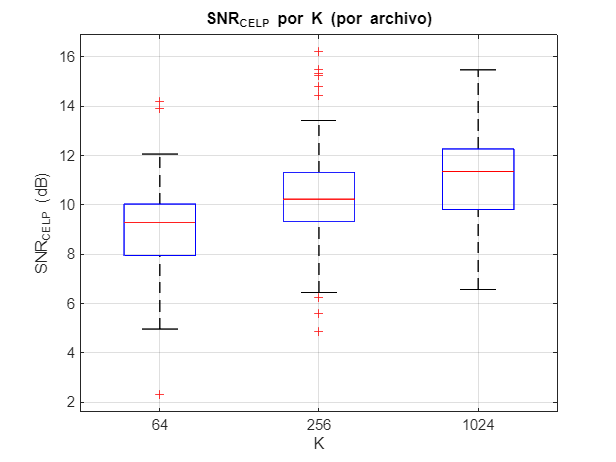


% ---------------- Gráficas de error (opcionales para el informe) ----------------
% Boxplot SNR por K (resumen por wav)
figure;
Ks = unique(results_b_wav.K);
grp = []; vals = [];
for j=1:numel(Ks)
    idx = results_b_wav.K == Ks(j);
    grp  = [grp;  j*ones(sum(idx),1)]; %#ok<AGROW>
    vals = [vals; results_b_wav.SNR_CELP_dB(idx)]; %#ok<AGROW>
end
boxplot(vals, grp, 'Labels', string(Ks));
grid on; ylabel('SNR_{CELP} (dB)'); xlabel('K');
title('SNR_{CELP} por K (por archivo)');

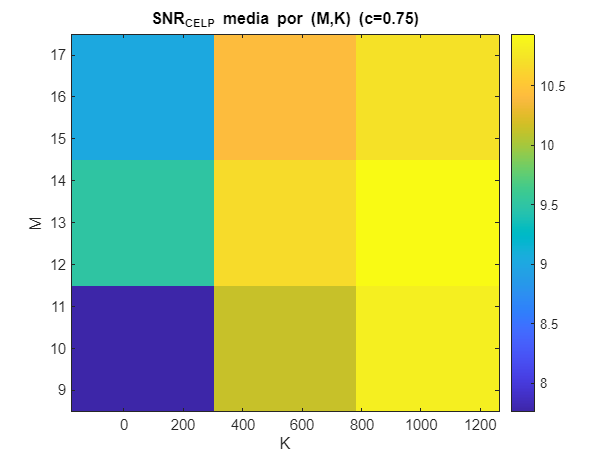


% Heatmap SNR por (M,K) a c=0.75 (resumen por wav)
figure;
c0 = 0.75; tol = 1e-6;
sel = abs(results_b_wav.c - c0) < tol;
Ms = unique(results_b_wav.M(sel)); Ks2 = unique(results_b_wav.K(sel));
A  = nan(numel(Ms), numel(Ks2));
for i=1:numel(Ms)
  for j=1:numel(Ks2)
    idx = sel & results_b_wav.M==Ms(i) & results_b_wav.K==Ks2(j);
    if any(idx), A(i,j) = mean(results_b_wav.SNR_CELP_dB(idx)); end
  end
end
imagesc(Ks2, Ms, A); axis xy; colorbar;
xlabel('K'); ylabel('M'); title(sprintf('SNR_{CELP} media por (M,K) (c=%.2f)', c0));

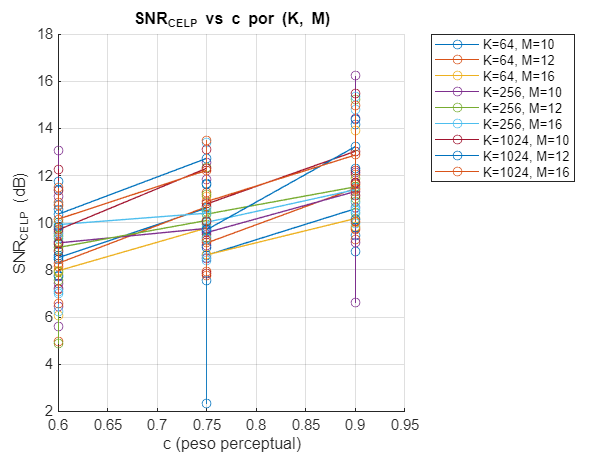


% Curvas SNR vs c por K (resumen por wav y por M)
figure; hold on; grid on;
Ks3 = unique(results_b_wav.K); Ms3 = unique(results_b_wav.M);
for j=1:numel(Ks3)
    for ii=1:numel(Ms3)
        selKM = results_b_wav.K==Ks3(j) & results_b_wav.M==Ms3(ii);
        if any(selKM)
            [cvals, ord] = sort(results_b_wav.c(selKM));
            snrvals = results_b_wav.SNR_CELP_dB(selKM);
            plot(cvals, snrvals(ord), '-o', 'DisplayName', sprintf('K=%d, M=%d', Ks3(j), Ms3(ii)));
        end
    end
end
xlabel('c (peso perceptual)'); ylabel('SNR_{CELP} (dB)');
title('SNR_{CELP} vs c por (K, M)');
legend('Location','bestoutside');

%% APARTADO (c) – Comparar voz sintetizada vs original (métricas + gráficas)
% Limpio y robusto: sin comas tras if/else, sin P_all mal dimensionado, fprintf seguro.

clc; close all;

% ---------- Configuración ----------
Fs_target = 8000;
N  = 160; L = 40; Pidx = [16 160];
rng(0);
DO_AUTOPICK = true;           % true: elige mejor caso (SNR) del (b); false: usa DEF abajo

% Parámetros por defecto si no hay resultados del (b) o si DO_AUTOPICK=false:
DEF.CB = struct('name','gauss1024','type','gaussian','K',1024);
DEF.M  = 16;
DEF.c  = 0.75;

% WAV a comparar (elige de tu carpeta)
wav_list = { 'we were away a year ago_lrr.wav', 'frase.wav', 'e.wav', 'r.wav', 'z.wav' };
wav_list = wav_list(cellfun(@isfile, wav_list));
assert(~isempty(wav_list), 'No se encontraron .wav en la carpeta.');
WAV_TO_USE = wav_list{1};     % cámbialo si quieres

% ---------- Cargar resultados del (b) si existen ----------
auto_case = DEF;
T = table();
try
    if exist('aparta_b_resultados_por_wav.csv','file')
        T = readtable('aparta_b_resultados_por_wav.csv');
    elseif exist('aparta_b_resultados.mat','file')
        S = load('aparta_b_resultados.mat');
        if isfield(S,'results_b_wav')
            T = S.results_b_wav;
        end
    end
catch
    T = table();
end

if DO_AUTOPICK && ~isempty(T)
    % Filtra filas del WAV que vamos a escuchar
    wav_col = string(T.wav);
    idxW = wav_col == string(WAV_TO_USE);
    if ~any(idxW)
        idxW = true(height(T),1); % si no hay filas de ese wav, usa todas
    end
    % Escoge el mejor por SNR_CELP_dB
    snrvec = T.SNR_CELP_dB(idxW);
    [~,kpos] = max(snrvec);
    idx = find(idxW);
    best = T(idx(kpos),:);

    % Extrae campos con conversión segura
    auto_case.CB = struct('name', toChar(best.codebook), ...
                          'type', toChar(best.cb_type), ...
                          'K',    double(best.K));
    auto_case.M  = double(best.M);
    auto_case.c  = double(best.c);

    fprintf('[(c) AUTO] Caso elegido por SNR: CB=%s(K=%d), M=%d, c=%.2f, wav=%s, SNR≈%.1f dB\n', ...
        toChar(auto_case.CB.name), auto_case.CB.K, auto_case.M, auto_case.c, ...
        toChar(best.wav), double(best.SNR_CELP_dB));
else
    fprintf('[(c) MANUAL/DEF] Usando CB=%s(K=%d), M=%d, c=%.2f, wav=%s\n', ...
        toChar(DEF.CB.name), DEF.CB.K, DEF.M, DEF.c, toChar(WAV_TO_USE));
end

[(c) AUTO] Caso elegido por SNR: CB=gauss1024(K=1024), M=10, c=0.90, wav=we were away a year ago_lrr.wav, SNR≈11.7 dB



% ---------- Cargar audio y normalizar ----------
[x,Fs] = audioread(WAV_TO_USE);
x = x(:,1);
if Fs ~= Fs_target
    x = resample(x, Fs_target, Fs);
    Fs = Fs_target;
end
x = x / (max(abs(x))+eps);
xlen = numel(x);

% ---------- Construir codebook ----------
cb = make_codebook(L, toChar(auto_case.CB.type), auto_case.CB.K);

% ---------- Síntesis completa (analysis-by-synthesis) ----------
F     = Pidx(2);
ebuf  = zeros(F,1); Zf = zeros(auto_case.M,1); Zw = zeros(auto_case.M,1); bbuf = 0;
ebuf2 = zeros(F,1); Zi = zeros(auto_case.M,1);

Tfrm  = floor(xlen/N);
y     = zeros(Tfrm*N,1);
P_list = [];                 % P por subtrama (lista simple)
segSNR = zeros(Tfrm,1);
LSD_fr = zeros(Tfrm,1);      % log-spectral distance por frame
nfft_spec = 512;

idx_write = 1;
for t = 1:Tfrm
    n = (t-1)*N + (1:N);
    xfrm = x(n);

    % Métrica espectral LPC del frame (para LSD frame-level)
    [ar,~,~,~] = lpcana(xfrm, auto_case.M);
    [~, LSD] = spec_metrics_from_lpc(xfrm, ar, nfft_spec);
    LSD_fr(t) = LSD;

    % Análisis CELP
    [kappa, k, theta0, P, b, ebuf, Zf, Zw] = celpana(xfrm, L, auto_case.M, auto_case.c, cb, Pidx, bbuf, ebuf, Zf, Zw); %#ok<ASGLU>
    P_list = [P_list; P(:)];

    % Síntesis CELP del frame
    [yfrm, ebuf2, Zi] = celpsyn(cb, kappa, k, theta0, P, b, ebuf2, Zi);
    y(idx_write:idx_write+N-1) = yfrm(:);
    idx_write = idx_write + N;

    % SNR segmental
    err = xfrm(:) - yfrm(:);
    segSNR(t) = 10*log10( (sum(xfrm.^2)+1e-12)/(sum(err.^2)+1e-12) );

    bbuf = b(end);
end

% Alinear longitudes
y      = y(1:Tfrm*N);
x_eval = x(1:Tfrm*N);
e      = x_eval - y;

% ---------- Métricas objetivas ----------
MSE       = mean(e.^2);
SNRg_dB   = 10*log10( (sum(x_eval.^2)+1e-12)/(sum(e.^2)+1e-12) );
segSNR_dB = mean( max(-10, min(35, segSNR)) );

% F0 a partir de P (limpieza basicona)
F0_vec_Hz = Fs ./ max(P_list, eps);
F0_vec_Hz(~isfinite(F0_vec_Hz) | F0_vec_Hz>400) = NaN;

% STOI / PESQ si existen
PESQ = NaN; STOI = NaN;
try
    if exist('pesq','file')==2
        PESQ = pesq(x_eval, y, Fs);
    end
catch
end
try
    if exist('stoi','file')==2
        STOI = stoi(x_eval, y, Fs);
    end
catch
end

fprintf('\n[(c) Métricas] WAV=%s\n', toChar(WAV_TO_USE));


[(c) Métricas] WAV=we were away a year ago_lrr.wav


fprintf('  CB=%s(K=%d), M=%d, c=%.2f\n', toChar(auto_case.CB.name), auto_case.CB.K, auto_case.M, auto_case.c);

  CB=gauss1024(K=1024), M=10, c=0.90


fprintf('  SNR global:     %.2f dB\n', SNRg_dB);

  SNR global:     11.75 dB


fprintf('  SNR segmental:  %.2f dB\n', segSNR_dB);

  SNR segmental:  12.22 dB


fprintf('  MSE:            %.3e\n', MSE);

  MSE:            1.895e-03


fprintf('  LSD medio:      %.2f dB\n', mean(LSD_fr));

  LSD medio:      43.84 dB


if ~isnan(PESQ)
    fprintf('  PESQ:           %.2f\n', PESQ);
end
if ~isnan(STOI)
    fprintf('  STOI:           %.2f\n', STOI);
end

  STOI:           0.92



% ---------- Gráficas comparativas ----------
t = (0:numel(x_eval)-1)/Fs;

% (1) Onda temporal (zoom ~0.4 s)
figure('Name','Temporal (zoom)');
Tzoom = min(round(0.4*Fs), numel(t));
plot(t(1:Tzoom), x_eval(1:Tzoom), 'k', 'LineWidth',1);
hold on;
plot(t(1:Tzoom), y(1:Tzoom), 'r');
grid on;
xlabel('Tiempo (s)'); ylabel('Amplitud');
title(sprintf('Original (negro) vs Síntesis (rojo) – Zoom (%.1f ms)', 1000*Tzoom/Fs));
legend('Original','Síntesis');

% (2) Señal de error
figure('Name','Error');
plot(t, e);
grid on;
xlabel('Tiempo (s)'); ylabel('Error');
title(sprintf('Señal de error (SNR=%.2f dB, SegSNR=%.2f dB)', SNRg_dB, segSNR_dB));

% (3) Espectrogramas comparados (misma escala)
win = hamming(256,'periodic');
ov = 200;
nfftS = 512;
[Sx, Fx, Tx] = spectrogram(x_eval, win, ov, nfftS, Fs, 'yaxis');
[Sy, Fy, Ty] = spectrogram(y,      win, ov, nfftS, Fs, 'yaxis');
mx = max([abs(Sx(:)); abs(Sy(:))])+eps;

figure('Name','Espectrograma original');
imagesc(Tx, Fx, 20*log10(abs(Sx)/mx + 1e-6));
axis xy; colorbar;
caxis([-60 0]);
xlabel('Tiempo (s)'); ylabel('Hz');
title('Original (escala común)');

figure('Name','Espectrograma síntesis');
imagesc(Ty, Fy, 20*log10(abs(Sy)/mx + 1e-6));
axis xy; colorbar;
caxis([-60 0]);
xlabel('Tiempo (s)'); ylabel('Hz');
title('Síntesis (escala común)');

% (4) LTAS – Espectro promedio (dB)
NfftL = 4096;
Xspec = abs(fft(x_eval .* hann(length(x_eval)), NfftL)).^2;
Yspec = abs(fft(y      .* hann(length(y     )), NfftL)).^2;
faxis = (0:NfftL/2)*Fs/NfftL;
Xltas = 10*log10( (Xspec(1:NfftL/2+1)+1e-12) );
Yltas = 10*log10( (Yspec(1:NfftL/2+1)+1e-12) );
figure('Name','LTAS');
plot(faxis, Xltas, 'k', 'LineWidth',1);
hold on;
plot(faxis, Yltas, 'r');
grid on;
xlim([0 4000]);
xlabel('Frecuencia (Hz)'); ylabel('dB');
title('LTAS – Espectro medio a largo plazo');
legend('Original','Síntesis');

% (5) Contorno F0 (a partir de P por subtrama)
if ~all(isnan(F0_vec_Hz))
    t_sub = linspace(0, numel(x_eval)/Fs, numel(F0_vec_Hz));
    figure('Name','F0');
    plot(t_sub, F0_vec_Hz, '.-');
    grid on;
    ylim([50 350]);
    xlabel('Tiempo (s)'); ylabel('F0 (Hz)');
    title('Contorno de F0 estimado (desde P del análisis CELP)');
end

% (6) Histograma SNR segmental
figure('Name','Histograma SegSNR');
histogram(segSNR, 'BinWidth', 1);
grid on;
xlabel('SNR segmental por trama (dB)'); ylabel('Recuentos');
title('Distribución de SNR segmental (clipping [-10, 35] dB)');

%% ===== Helpers =====
function s = toChar(x)
% Convierte cellstr/string/char/num a char para fprintf
if iscell(x) && ~isempty(x)
    x = x{1};
end
if isstring(x)
    x = char(x);
elseif isnumeric(x)
    x = num2str(x);
end
if ~ischar(x)
    x = char(string(x));
end
s = x;
end

%% (c) PRUEBA AUDITIVA – A/B/ABX para original vs síntesis
clc; clear; close all;

% ----------------- Configuración -----------------
Fs_target = 8000;                         % Fs de trabajo
sil = zeros(round(0.35*Fs_target),1);    % silencio entre fragmentos (0.35 s)
outdir = "c_auditivo_out"; if ~isfolder(outdir), mkdir(outdir); end

% Lista de pares (ajústala si hace falta)
orig_files  = { ...
    "we were away a year ago_lrr.wav" ...
    % añade más aquí
};
synth_files = { ...
    "we were away a year ago_lrr.wav" ...
    % nombres pareados con los de arriba
};

assert(numel(orig_files)==numel(synth_files), "orig_files y synth_files deben tener la misma longitud.");

% ----------------- Bucle por pares -----------------
logTAB = table();  % aquí se guarda el log de ABX (si lo haces)
for k = 1:numel(orig_files)
    fO = orig_files{k}; fS = synth_files{k};
    assert(isfile(fO), "No existe: %s", fO);
    assert(isfile(fS), "No existe: %s", fS);

    % --- lee y preprocesa (mono, re-muestreo, normalización) ---
    [xo, FsO] = audioread(fO); xo = mean(xo,2);
    [xs, FsS] = audioread(fS); xs = mean(xs,2);
    if FsO ~= Fs_target, xo = resample(xo, Fs_target, FsO); end
    if FsS ~= Fs_target, xs = resample(xs, Fs_target, FsS); end

    % --- recorta bordes silenciosos comunes (opcional, robusto) ---
    [xo, xs] = trim_common_silence(xo, xs, Fs_target);

    % --- alinea por retardo (GCC/xcorr) y empareja longitudes ---
    [xoA, xsA, lag_s] = align_by_xcorr(xo, xs, Fs_target, 0.05); %#ok<ASGLU>

    % --- iguala nivel (RMS) para comparación justa ---
    [xoN, xsN] = match_rms(xoA, xsA);

    % --- genera diferencias y conjuntos para escucha (A, B y A-B) ---
    diff_sig = xoN - xsN;
    AB      = [xoN; sil; xsN];             % Original→Síntesis
    BA      = [xsN; sil; xoN];             % Síntesis→Original
    ABdiff  = [xoN; sil; xsN; sil; diff_sig];

    % --- exporta WAVs útiles para escucha externa ---
    base = erase(fO, ".wav");
    audiowrite(fullfile(outdir, base + "_AB.wav"), AB, Fs_target);
    audiowrite(fullfile(outdir, base + "_BA.wav"), BA, Fs_target);
    audiowrite(fullfile(outdir, base + "_AB_diff.wav"), ABdiff, Fs_target);
    audiowrite(fullfile(outdir, base + "_ORIG_aligned.wav"), xoN, Fs_target);
    audiowrite(fullfile(outdir, base + "_SYN_aligned.wav"),  xsN, Fs_target);
    audiowrite(fullfile(outdir, base + "_DIFF.wav"),         diff_sig, Fs_target);

    fprintf('[%02d] Exportados: %s_AB/BA/AB_diff (+ ORIG/SYN/DIFF)\n', k, base);

    % --- reproductor rápido en MATLAB (teclas) ---
    fprintf('--- ABX rápido para: %s ---\n', base);
    fprintf('Teclas: A=Original, B=Síntesis, X=aleatorio, P=pausa/stop, R=revelar, \n');
    fprintf('         1..5=preferencia B sobre A (1: A mucho mejor, 5: B mucho mejor), Q=salir caso\n');

    [rez, logcase] = abx_quick_test(xoN, xsN, Fs_target, base); %#ok<ASGLU>
    logTAB = [logTAB; logcase]; %#ok<AGROW>
end

[01] Exportados: we were away a year ago_lrr_AB/BA/AB_diff (+ ORIG/SYN/DIFF)


--- ABX rápido para: we were away a year ago_lrr ---


Teclas: A=Original, B=Síntesis, X=aleatorio, P=pausa/stop, R=revelar, 


         1..5=preferencia B sobre A (1: A mucho mejor, 5: B mucho mejor), Q=salir caso


ABX (we were away a year ago_lrr): pulsa teclas A/B/X, 1..5, R, P, Q.
  → X era: A



% ----------------- guarda el log de ABX -----------------
writetable(logTAB, fullfile(outdir, "abx_log.csv"));
disp('Log guardado en c_auditivo_out/abx_log.csv');

Log guardado en c_auditivo_out/abx_log.csv



%% ------------ FUNCIONES AUXILIARES (locales) ------------

function [x1t, x2t] = trim_common_silence(x1, x2, Fs)
% Recorte suave de bordes silenciosos comunes usando energía por frames
N = round(0.02*Fs); H = round(0.01*Fs);
e1 = frame_energy(x1,N,H); e2 = frame_energy(x2,N,H);
th = 0.001; % umbral relativo
i1 = find(e1>th*max(e1), 1, 'first'); j1 = find(e1>th*max(e1), 1, 'last');
i2 = find(e2>th*max(e2), 1, 'first'); j2 = find(e2>th*max(e2), 1, 'last');
i = max(i1,i2); j = min(j1,j2);
i = max(i-2,1); j = min(j+2, min(numel(e1),numel(e2)));
t1 = ((i-1)*H+1):min((j-1)*H+N, numel(x1));
t2 = ((i-1)*H+1):min((j-1)*H+N, numel(x2));
x1t = x1(t1); x2t = x2(t2);
end

function e = frame_energy(x,N,H)
% Energía por frames con solapamiento
M = 1+floor((numel(x)-N)/H);
e = zeros(M,1);
for m=1:M
    ii = (m-1)*H+(1:N);
    w = hann(N,'periodic');
    xx = x(ii).*w;
    e(m) = sum(xx.^2);
end
end

function [x1a, x2a, lag_s] = align_by_xcorr(x1, x2, Fs, maxLagSec)
% Alineado por correlación cruzada limitada a +/- maxLagSec
maxLag = round(maxLagSec*Fs);
[cc, lags] = xcorr(x1, x2, maxLag, 'coeff');
[~, I] = max(cc);
lag = lags(I);                 % lag>0: x1 adelantado respecto a x2
lag_s = lag/Fs;

if lag > 0
    x2a = padarray(x2, lag, 0, 'pre');
    x1a = padarray(x1, numel(x2a)-numel(x1), 0, 'post');
    x2a = padarray(x2a, numel(x1a)-numel(x2a), 0, 'post');
elseif lag < 0
    lag = -lag;
    x1a = padarray(x1, lag, 0, 'pre');
    x2a = padarray(x2, numel(x1a)-numel(x2), 0, 'post');
    x1a = padarray(x1a, numel(x2a)-numel(x1a), 0, 'post');
else
    x1a = x1; x2a = x2;
end

L = min(numel(x1a), numel(x2a));
x1a = x1a(1:L); x2a = x2a(1:L);
end

function [xa, xb] = match_rms(xa, xb)
% Igualación por RMS (evita sesgos de nivel)
rA = sqrt(mean(xa.^2)+eps);
rB = sqrt(mean(xb.^2)+eps);
g  = rA/rB;
xb  = xb * g;
% evita clipping
mx = max([abs(xa(:)); abs(xb(:))]); if mx>1, xa=xa/mx; xb=xb/mx; end
end

function [rez, logcase] = abx_quick_test(xA, xB, Fs, tag)
% Test ABX mínimo con teclas.
% - A: reproduce A (Original)
% - B: reproduce B (Síntesis)
% - X: reproduce una de las dos al azar
% - 1..5: rating de preferencia (1 → A mucho mejor, 5 → B mucho mejor)
% - R: revela qué es X
% - P: pausa/stop
% - Q: termina caso
fprintf('ABX (%s): pulsa teclas A/B/X, 1..5, R, P, Q.\n', tag);

% Mapeo de X
map = randi(2);          % 1->A, 2->B
if map == 1
    Xsig = xA; whoX = "A";
else
    Xsig = xB; whoX = "B";
end

apA = audioplayer(xA, Fs);
apB = audioplayer(xB, Fs);
apX = audioplayer(Xsig, Fs);

ratings = []; 
actions = strings(0,1);  % vector string vacío
tStart  = datetime('now');

while true
    w = input('>> Tecla [A/B/X/1..5/R/P/Q]: ','s');
    if isempty(w), continue; end
    w = upper(string(w(1)));

    switch w
        case "A"
            stop(apA); stop(apB); stop(apX);
            playblocking(apA);
            actions(end+1,1) = "playA";
        case "B"
            stop(apA); stop(apB); stop(apX);
            playblocking(apB);
            actions(end+1,1) = "playB";
        case "X"
            stop(apA); stop(apB); stop(apX);
            playblocking(apX);
            actions(end+1,1) = "playX";
        case {"1","2","3","4","5"}
            ratings(end+1) = str2double(w); %#ok<AGROW>
            fprintf('  (rating registrado = %d)\n', ratings(end));
        case "R"
            fprintf('  → X era: %s\n', whoX);
        case "P"
            stop(apA); stop(apB); stop(apX);
        case "Q"
            break;
        otherwise
            disp('   tecla no válida.');
    end
end

tEnd = datetime('now');
rez.tag = tag; rez.Xis = whoX; rez.ratings = ratings; rez.actions = actions;

% log en tabla
logcase = table(string(tag), string(whoX), uint16(numel(ratings)), ...
                mean_or_nan(ratings), std_or_nan(ratings), ...
                tStart, tEnd, ...
                'VariableNames', {'tag','X_is','n_ratings','rating_mean','rating_std','t_start','t_end'});
end


function m = mean_or_nan(x), if isempty(x), m=nan; else, m=mean(x); end, end
function s = std_or_nan(x),  if isempty(x), s=nan; else, s=std(x);  end, end







%% APARTADO (d) – Transmisión a distintas velocidades (bitrates) y evaluación de calidad
% - Define perfiles de “bitrate” (asignación de bits por parámetro/subtrama/marco)
% - Cuantiza P, b y theta0 según cada perfil (k usa log2(K) bits implícitos)
% - Sintetiza con parámetros cuantizados y evalúa SNR/MSE/PESQ/STOI
% - Gráficas: SNR vs bitrate y boxplot por perfil

clc; close all;

% ----- Parámetros base (como en a/b) -----
Fs_target = 8000; N = 160; L = 40; Pidx = [16 160]; rng(0);
J = N / L;                 % # subtramas por trama (4 con N=160, L=40)
FPS = Fs_target / N;       % tramas por segundo (=50 @ 8kHz y N=160)

% ----- Audio a evaluar -----
wav_list = { 'we were away a year ago_lrr.wav', 'frase.wav', 'e.wav', 'r.wav', 'z.wav' };
wav_list = wav_list(cellfun(@isfile, wav_list));
assert(~isempty(wav_list), 'No se encontraron .wav en la carpeta.');

% ----- Perfiles de transmisión (puedes ajustar los bits) -----
% Nota: bits_frame = J*(bits_k + bits_P + bits_b + bits_theta0) + bits_LPC + bits_flags
% El bitrate real = bits_frame * FPS
PROFILES = [ ...
    struct('name','Low-6k',  'cb',struct('type','gaussian','K',64),   'M',10, 'c',0.75, ...
           'bits_k',6,'bits_P',7,'bits_b',4,'bits_theta0',5,'bits_LPC',28,'bits_flags',1);  % ≈6.0–6.5 kbps
    struct('name','Mid-9.6k','cb',struct('type','gaussian','K',256),  'M',12, 'c',0.75, ...
           'bits_k',8,'bits_P',8,'bits_b',5,'bits_theta0',6,'bits_LPC',84,'bits_flags',1);  % ≈9.5–10 kbps
    struct('name','High-16k','cb',struct('type','gaussian','K',1024), 'M',16, 'c',0.75, ...
           'bits_k',10,'bits_P',8,'bits_b',6,'bits_theta0',7,'bits_LPC',196,'bits_flags',1);% ≈16 kbps
    struct('name','Alg-8k',  'cb',struct('type','2pulses','K',256),   'M',12, 'c',0.75, ...
           'bits_k',8,'bits_P',8,'bits_b',5,'bits_theta0',6,'bits_LPC',48,'bits_flags',1)   % ≈8–9 kbps
];

% ----- Ajustes de cuantización -----
Pmin = Pidx(1); Pmax = Pidx(2);                  % rango de pitch (muestras)
b_min = 0.00; b_max = 0.95;                      % rango de b
% Cuantización log para |theta0|: mapear log10(|theta0|) en [logmin, logmax]
th_logmin = -3.0; th_logmax = 0.6;               % ~ [0.001, 3.98]
TH_EPS = 1e-6;

% ----- Opciones -----
SAVE_WAVS = false;     % guarda audios sintetizados por perfil
TRY_PESQ  = exist('pesq','file')==2;
TRY_STOI  = exist('stoi','file')==2;

% ----- Resultados -----
res_d_summary = table();
res_d_detail  = table();

fprintf('\n=== APARTADO (d): Transmisión a distintas velocidades ===\n');


=== APARTADO (d): Transmisión a distintas velocidades ===



for ip = 1:numel(PROFILES)
    PFL = PROFILES(ip);
    bits_per_frame = J*(PFL.bits_k + PFL.bits_P + PFL.bits_b + PFL.bits_theta0) ...
                     + PFL.bits_LPC + PFL.bits_flags;
    bitrate_bps = bits_per_frame * FPS;
    bitrate_kbps = bitrate_bps / 1000;

    % Construir codebook del perfil
    cb = make_codebook(L, PFL.cb.type, PFL.cb.K);

    fprintf('[Perfil %s] K=%d, M=%d, c=%.2f | bits/frame=%d (≈ %.2f kbps)\n', ...
        toChar(PFL.name), PFL.cb.K, PFL.M, PFL.c, bits_per_frame, bitrate_kbps);

    % Métricas acumuladas por wav
    SNRg = []; SegSNR = []; MSEv = []; PESQv = []; STOIv = [];

    for iw = 1:numel(wav_list)
        fname = wav_list{iw};
        [x,Fs] = audioread(fname); x = x(:,1);
        if Fs ~= Fs_target, x = resample(x, Fs_target, Fs); end
        x = x / (max(abs(x))+eps);

        % Estados de análisis y síntesis
        F     = Pidx(2);
        ebuf  = zeros(F,1); Zf = zeros(PFL.M,1); Zw = zeros(PFL.M,1); bbuf = 0;
        ebuf2 = zeros(F,1); Zi = zeros(PFL.M,1);

        T = floor(numel(x)/N);
        y = zeros(T*N,1);
        idxw = 1;

        segsnr_frames = zeros(T,1);

        for t = 1:T
            n = (t-1)*N + (1:N);
            xfrm = x(n);

            % --- ANÁLISIS CELP en este perfil ---
            [kappa, k, theta0, P, b, ebuf, Zf, Zw] = celpana(xfrm, L, PFL.M, PFL.c, cb, Pidx, bbuf, ebuf, Zf, Zw); %#ok<ASGLU>

            % --- CUANTIZACIÓN de parámetros ---
            % k: índice del codebook -> usa implícitamente log2(K) bits (no alteramos)
            % P: uniforme en [Pmin,Pmax] con bits_P
            Pq  = q_uniform(P, Pmin, Pmax, PFL.bits_P);
            Pq  = max(Pmin, min(Pmax, round(Pq)));   % lag entero válido

            % b: uniforme en [b_min,b_max]
            bq  = q_uniform(b, b_min, b_max, PFL.bits_b);

            % theta0: cuantización log de |theta0| + bit de signo
            th_sign = sign(theta0); th_sign(th_sign==0) = 1;
            mag     = abs(theta0) + TH_EPS;
            lmag    = log10(mag);
            lmag_q  = q_uniform(lmag, th_logmin, th_logmax, max(PFL.bits_theta0-1,1)); % -1 para el signo
            mag_q   = 10.^lmag_q;
            theta0q = th_sign .* mag_q;

            % --- SÍNTESIS con parámetros cuantizados ---
            [yfrm, ebuf2, Zi] = celpsyn(cb, kappa, k, theta0q, Pq, bq, ebuf2, Zi);
            y(idxw:idxw+N-1) = yfrm(:);
            idxw = idxw + N;

            % SNR segmental
            err = xfrm(:) - yfrm(:);
            segsnr_frames(t) = 10*log10( (sum(xfrm.^2)+1e-12)/(sum(err.^2)+1e-12) );

            bbuf = b(end);
        end

        % Recorte y métricas por wav
        y = y(1:T*N);
        x_eval = x(1:T*N);
        e = x_eval - y;

        mse_wav    = mean(e.^2);
        snr_global = 10*log10( (sum(x_eval.^2)+1e-12)/(sum(e.^2)+1e-12) );
        segsnr_wav = mean( max(-10, min(35, segsnr_frames)) );

        pesq_val = NaN; stoi_val = NaN;
        if TRY_PESQ
            try, pesq_val = pesq(x_eval, y, Fs_target); catch, end
        end
        if TRY_STOI
            try, stoi_val = stoi(x_eval, y, Fs_target); catch, end
        end

        SNRg(end+1)   = snr_global; %#ok<SAGROW>
        SegSNR(end+1) = segsnr_wav; %#ok<SAGROW>
        MSEv(end+1)   = mse_wav;    %#ok<SAGROW>
        PESQv(end+1)  = pesq_val;   %#ok<SAGROW>
        STOIv(end+1)  = stoi_val;   %#ok<SAGROW>

        if SAVE_WAVS
            outname = sprintf('d_synth_%s_%s.wav', toChar(PFL.name), stripExt(fname));
            audiowrite(outname, y, Fs_target);
        end

        % Detalle por wav y perfil
        res_d_detail = [res_d_detail; table( ...
            string(PFL.name), double(bitrate_kbps), uint32(PFL.cb.K), string(PFL.cb.type), uint32(PFL.M), PFL.c, ...
            string(fname), snr_global, segsnr_wav, mse_wav, pesq_val, stoi_val, ...
            'VariableNames', {'perfil','bitrate_kbps','K','cb_type','M','c','wav', ...
                              'SNR_CELPq_dB','SegSNR_CELPq_dB','MSE','PESQ','STOI'})]; %#ok<AGROW>
    end

    % Resumen por perfil
    res_d_summary = [res_d_summary; table( ...
        string(PFL.name), double(bitrate_kbps), uint32(PFL.cb.K), string(PFL.cb.type), uint32(PFL.M), PFL.c, ...
        mean(SNRg), mean(SegSNR), mean(MSEv), mean(PESQv,'omitnan'), mean(STOIv,'omitnan'), ...
        'VariableNames', {'perfil','bitrate_kbps','K','cb_type','M','c', ...
                          'SNR_CELPq_dB_mean','SegSNR_CELPq_dB_mean','MSE_mean','PESQ_mean','STOI_mean'})]; %#ok<AGROW>
end

[Perfil Low-6k] K=64, M=10, c=0.75 | bits/frame=117 (≈ 5.85 kbps)
[Perfil Mid-9.6k] K=256, M=12, c=0.75 | bits/frame=193 (≈ 9.65 kbps)
[Perfil High-16k] K=1024, M=16, c=0.75 | bits/frame=321 (≈ 16.05 kbps)
[Perfil Alg-8k] K=256, M=12, c=0.75 | bits/frame=157 (≈ 7.85 kbps)



% ----- Guardado -----
writetable(res_d_summary, 'aparta_d_resumen.csv');
writetable(res_d_detail,  'aparta_d_por_wav.csv');
save('aparta_d_resultados.mat', 'res_d_summary', 'res_d_detail');

disp('Resumen por perfil:');

Resumen por perfil:


disp(res_d_summary);

      perfil      bitrate_kbps     K       cb_type      M      c      SNR_CELPq_dB_mean    SegSNR_CELPq_dB_mean    MSE_mean     PESQ_mean    STOI_mean
    __________    ____________    ____    __________    __    ____    _________________    ____________________    _________    _________    _________

    "Low-6k"          5.85          64    "gaussian"    10    0.75         3.1998                 2.7876           0.0074691       NaN        0.82407 
    "Mid-9.6k"        9.65         256    "gaussian"    12    0.75          7.368                 4.4198            0.003928       NaN        0.86366 
    "High-16k"       

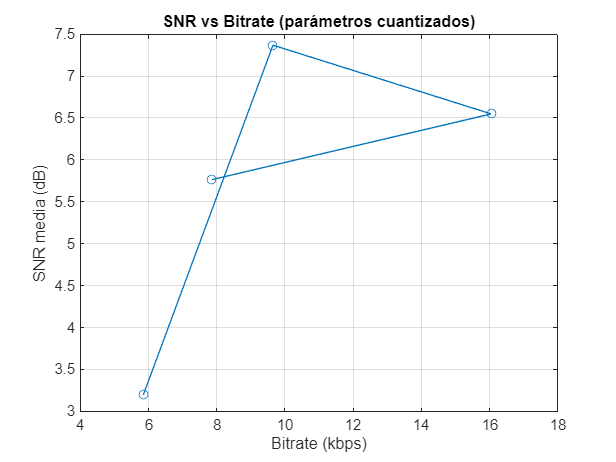


% ----- Gráficas -----
% (1) SNR vs bitrate
figure; plot(res_d_summary.bitrate_kbps, res_d_summary.SNR_CELPq_dB_mean, '-o'); grid on;
xlabel('Bitrate (kbps)'); ylabel('SNR media (dB)'); title('SNR vs Bitrate (parámetros cuantizados)');

xlim([4.1 18.0])
ylim([3.00 7.48])

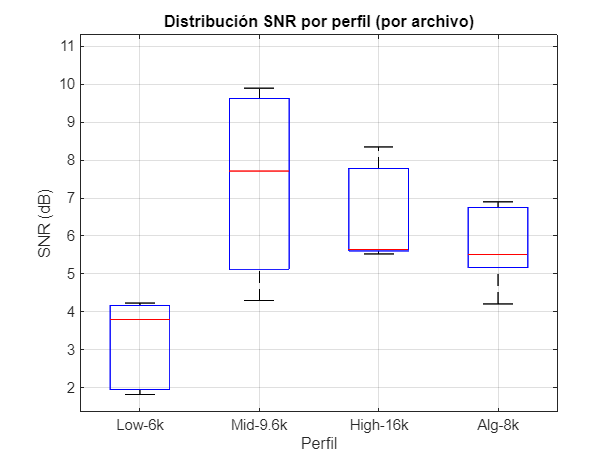


% (2) Boxplot SNR por perfil (detalle por wav)
figure;
perfs = unique(res_d_detail.perfil,'stable');
grp = []; vals = [];
for j=1:numel(perfs)
    idx = res_d_detail.perfil == perfs(j);
    grp  = [grp;  j*ones(sum(idx),1)]; %#ok<AGROW>
    vals = [vals; res_d_detail.SNR_CELPq_dB(idx)]; %#ok<AGROW>
end
boxplot(vals, grp, 'Labels', cellstr(perfs)); grid on;
ylabel('SNR (dB)'); xlabel('Perfil'); title('Distribución SNR por perfil (por archivo)');


%% ================== Helpers locales ==================
function y = q_uniform(x, xmin, xmax, nbits)
% Cuantizador uniforme saturante con nbits -> 2^nbits niveles
x = double(x);
if nbits <= 0
    y = min(max(x, xmin), xmax);
    return;
end
L = 2^nbits;
x = min(max(x, xmin), xmax);
step = (xmax - xmin) / (L - 1);
y = xmin + round((x - xmin)/step) * step;
end



function name = stripExt(fname)
[~,n,~] = fileparts(fname); name = n;
end

%% APARTADO (e) – Comparar vocoders CELP vs LP: errores y calidad
% - Autoelige el mejor caso CELP del (b) si existe; si no, usa DEF.
% - LP vocoder simple: LPC por trama + voi/unvoi -> excitación (pulso/ruido) + 1/A(z).
% - Métricas: MSE, SNR global, SNR seg., LSD (y opcional PESQ/STOI).
% - Salidas: CSV/MAT + gráficas comparativas.

clc; close all;

% ---------- Configuración común ----------
Fs_target = 8000;
N  = 160;             % 20 ms
L  = 40;              % 5 ms (para CELP)
Pidx = [16 160];      % pitch-lag para CELP (2..20 ms)
rng(0);
nfft_spec = 512;      % para LSD

% WAVs a evaluar
wav_list = { 'we were away a year ago_lrr.wav', 'frase.wav', 'e.wav', 'r.wav', 'z.wav' };
wav_list = wav_list(cellfun(@isfile, wav_list));
assert(~isempty(wav_list), 'No se encontraron .wav en la carpeta.');

% ---------- Selección del caso CELP ----------
DEF.CB = struct('name','gauss1024','type','gaussian','K',1024);
DEF.M  = 16;
DEF.c  = 0.75;

celp_case = DEF;
T_b = table();
try
    if exist('aparta_b_resultados_por_wav.csv','file')
        T_b = readtable('aparta_b_resultados_por_wav.csv');
    elseif exist('aparta_b_resultados.mat','file')
        S = load('aparta_b_resultados.mat');
        if isfield(S,'results_b_wav'), T_b = S.results_b_wav; end
    end
catch
    T_b = table();
end

if ~isempty(T_b)
    % Tomamos el MEJOR caso por SNR medio (sobre todos los wavs)
    [~,pos] = max(T_b.SNR_CELP_dB);
    best = T_b(pos,:);
    celp_case.CB = struct('name', toChar(best.codebook), 'type', toChar(best.cb_type), 'K', double(best.K));
    celp_case.M  = double(best.M);
    celp_case.c  = double(best.c);
    fprintf('[(e) AUTO] Caso CELP: %s (K=%d), M=%d, c=%.2f\n', toChar(celp_case.CB.name), celp_case.CB.K, celp_case.M, celp_case.c);
else
    fprintf('[(e) DEF]  Caso CELP: %s (K=%d), M=%d, c=%.2f\n', toChar(DEF.CB.name), DEF.CB.K, DEF.M, DEF.c);
end

[(e) AUTO] Caso CELP: 2pulses256 (K=256), M=10, c=0.90



% ---------- Tablas de resultados ----------
T_detail = table();   % una fila por (wav, vocoder)
T_summary = table();  % agregados por vocoder

% ---------- Bucle por WAVs ----------
for iw = 1:numel(wav_list)
    fname = wav_list{iw};
    [x,Fs] = audioread(fname);
    x = x(:,1);
    if Fs ~= Fs_target
        x = resample(x, Fs_target, Fs);
    end
    x = x / (max(abs(x))+eps);
    xlen = numel(x);
    Tfrm = floor(xlen/N);

    % ====== (1) CELP: análisis-síntesis con el caso elegido ======
    cb = make_codebook(L, toChar(celp_case.CB.type), celp_case.CB.K);

    F     = Pidx(2);
    ebuf  = zeros(F,1); Zf = zeros(celp_case.M,1); Zw = zeros(celp_case.M,1); bbuf = 0;
    ebuf2 = zeros(F,1); Zi = zeros(celp_case.M,1);

    y_celp = zeros(Tfrm*N,1);
    segSNR_celp = zeros(Tfrm,1);
    LSD_celp_fr = zeros(Tfrm,1);

    wr = 1;
    for t = 1:Tfrm
        idx = (t-1)*N + (1:N);
        xfrm = x(idx);

        % LSD frame: a modo de referencia (LPC del frame)
        [ar,~,~,~] = lpcana(xfrm, celp_case.M);
        [~,LSDfr]  = spec_metrics_from_lpc(xfrm, ar, nfft_spec);
        LSD_celp_fr(t) = LSDfr;

        [kappa, k, theta0, P, b, ebuf, Zf, Zw] = celpana(xfrm, L, celp_case.M, celp_case.c, cb, Pidx, bbuf, ebuf, Zf, Zw); %#ok<ASGLU>
        [yfrm, ebuf2, Zi] = celpsyn(cb, kappa, k, theta0, P, b, ebuf2, Zi);
        y_celp(wr:wr+N-1) = yfrm(:);
        wr = wr + N;

        err = xfrm(:) - yfrm(:);
        segSNR_celp(t) = 10*log10( (sum(xfrm.^2)+1e-12)/(sum(err.^2)+1e-12) );

        bbuf = b(end);
    end

    % Métricas CELP
    y_celp = y_celp(1:Tfrm*N);
    x_eval = x(1:Tfrm*N);
    e_celp = x_eval - y_celp;

    MSE_celp      = mean(e_celp.^2);
    SNRg_celp_dB  = 10*log10( (sum(x_eval.^2)+1e-12)/(sum(e_celp.^2)+1e-12) );
    SegSNR_celp_dB= mean( max(-10, min(35, segSNR_celp)) );
    LSD_celp_dB   = mean(LSD_celp_fr);

    PESQ_celp = NaN; STOI_celp = NaN;
    try
        if exist('pesq','file')==2, PESQ_celp = pesq(x_eval, y_celp, Fs_target); end
    catch
    end
    try
        if exist('stoi','file')==2, STOI_celp = stoi(x_eval, y_celp, Fs_target); end
    catch
    end

    % Añadir detalle CELP
    T_detail = [T_detail; table( ...
        string(fname), string('CELP'), double(MSE_celp), double(SNRg_celp_dB), double(SegSNR_celp_dB), double(LSD_celp_dB), ...
        double(PESQ_celp), double(STOI_celp), ...
        'VariableNames', {'wav','vocoder','MSE','SNR_dB','SegSNR_dB','LSD_dB','PESQ','STOI'})]; %#ok<AGROW>

    % ====== (2) LP vocoder: LPC + excitación periódica/ruido + 1/A(z) ======
    % par LP (usa mismo orden M del caso CELP para comparación justa)
    M_LP = celp_case.M;

    % Estados del filtro LP para continuidad entre tramas
    Zi_lp = zeros(M_LP,1);

    y_lp = zeros(Tfrm*N,1);
    segSNR_lp = zeros(Tfrm,1);
    LSD_lp_fr = zeros(Tfrm,1);

    wr = 1;
    for t = 1:Tfrm
        idx = (t-1)*N + (1:N);
        xfrm = x(idx);

        % Análisis LPC del frame
        [ar, g, ~, ehat] = lpcana(xfrm, M_LP);  %#ok<NASGU>  % ar: [1 -a1 ... -aM], g: ganancia

        % Métrica espectral frame para LP
        [~,LSDfr]  = spec_metrics_from_lpc(xfrm, ar, nfft_spec);
        LSD_lp_fr(t) = LSDfr;

        % Voiced/Unvoiced y pitch estimado (autocorr. simple)
        vu = safe_voiunvoi(xfrm);
        P0 = est_pitch_acf(xfrm, Fs_target, [Pidx(1), Pidx(2)]); % lag en muestras

        % Excitación:
        if vu==1 && ~isnan(P0) && P0>0
            e_syn = pulse_train(N, P0);           % tren de impulsos
        else
            e_syn = randn(N,1);                   % ruido blanco
        end
        % Escalar excitación a la energía del residuo estimado
        rms_ehat = sqrt(mean(ehat.^2)+1e-12);
        e_syn = e_syn * rms_ehat;

        % Síntesis LP: pasa excitación por 1/A(z)
        [yfrm, Zi_lp] = filter(1, ar, e_syn, Zi_lp);

        % Escribe y calcula SNR seg.
        y_lp(wr:wr+N-1) = yfrm(:);
        wr = wr + N;

        err = xfrm(:) - yfrm(:);
        segSNR_lp(t) = 10*log10( (sum(xfrm.^2)+1e-12)/(sum(err.^2)+1e-12) );
    end

    % Métricas LP
    y_lp = y_lp(1:Tfrm*N);
    e_lp = x_eval - y_lp;

    MSE_lp      = mean(e_lp.^2);
    SNRg_lp_dB  = 10*log10( (sum(x_eval.^2)+1e-12)/(sum(e_lp.^2)+1e-12) );
    SegSNR_lp_dB= mean( max(-10, min(35, segSNR_lp)) );
    LSD_lp_dB   = mean(LSD_lp_fr);

    PESQ_lp = NaN; STOI_lp = NaN;
    try
        if exist('pesq','file')==2, PESQ_lp = pesq(x_eval, y_lp, Fs_target); end
    catch
    end
    try
        if exist('stoi','file')==2, STOI_lp = stoi(x_eval, y_lp, Fs_target); end
    catch
    end

    % Añadir detalle LP
    T_detail = [T_detail; table( ...
        string(fname), string('LP'), double(MSE_lp), double(SNRg_lp_dB), double(SegSNR_lp_dB), double(LSD_lp_dB), ...
        double(PESQ_lp), double(STOI_lp), ...
        'VariableNames', {'wav','vocoder','MSE','SNR_dB','SegSNR_dB','LSD_dB','PESQ','STOI'})]; %#ok<AGROW>
end

% ---------- Resúmenes ----------
G = groupsummary(T_detail, 'vocoder', 'mean', {'MSE','SNR_dB','SegSNR_dB','LSD_dB','PESQ','STOI'});
T_summary = G;

% Guardar
writetable(T_detail,  'aparta_e_detalle_por_wav.csv');
writetable(T_summary, 'aparta_e_resumen.csv');
save('aparta_e_resultados.mat', 'T_detail', 'T_summary', 'celp_case');

disp('=== Resumen (promedio sobre WAVs) ===');

=== Resumen (promedio sobre WAVs) ===


disp(T_summary);

    vocoder    GroupCount     mean_MSE     mean_SNR_dB    mean_SegSNR_dB    mean_LSD_dB    mean_PESQ    mean_STOI
    _______    __________    __________    ___________    ______________    ___________    _________    _________

    "CELP"         5         0.00099353       11.968          7.3115          63.345          NaN        0.90156 
    "LP"           5           0.017742     -0.50969         -1.9816          63.345          NaN         0.5813 



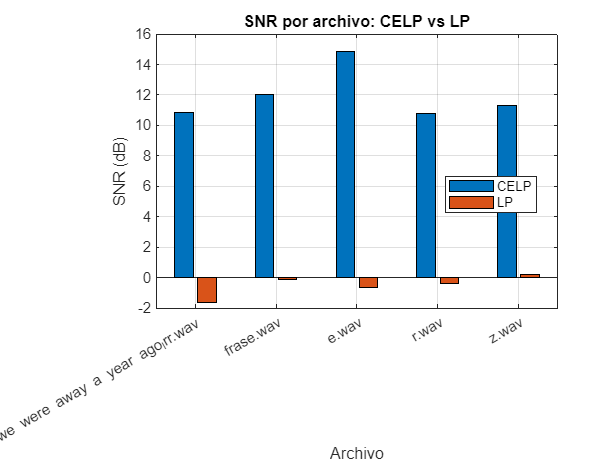


% ---------- Gráficas comparativas ----------
% (1) Barras por WAV: CELP vs LP (SNR global)
figure; 
wavs = unique(T_detail.wav, 'stable');
SNR_c = nan(numel(wavs),1); SNR_l = nan(numel(wavs),1);
for i=1:numel(wavs)
    SNR_c(i) = T_detail.SNR_dB(T_detail.wav==wavs(i) & T_detail.vocoder=="CELP");
    SNR_l(i) = T_detail.SNR_dB(T_detail.wav==wavs(i) & T_detail.vocoder=="LP");
end
b = bar([SNR_c SNR_l]); grid on;
set(gca,'XTick',1:numel(wavs),'XTickLabel',cellstr(wavs));
xlabel('Archivo'); ylabel('SNR (dB)');
legend({'CELP','LP'},'Location','best'); title('SNR por archivo: CELP vs LP');

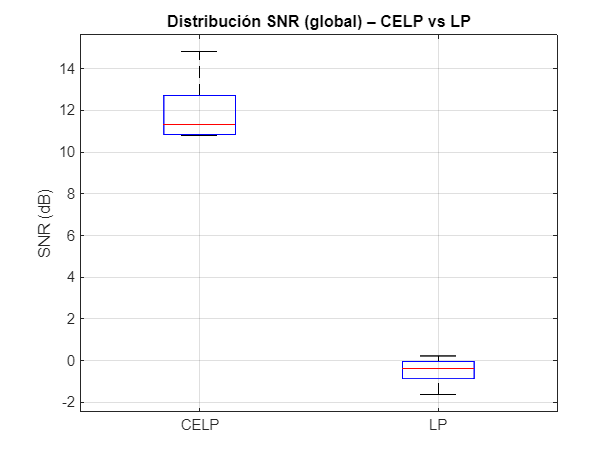


% (2) Boxplot global SNR
figure;
boxplot(T_detail.SNR_dB, T_detail.vocoder);
grid on; ylabel('SNR (dB)'); title('Distribución SNR (global) – CELP vs LP');

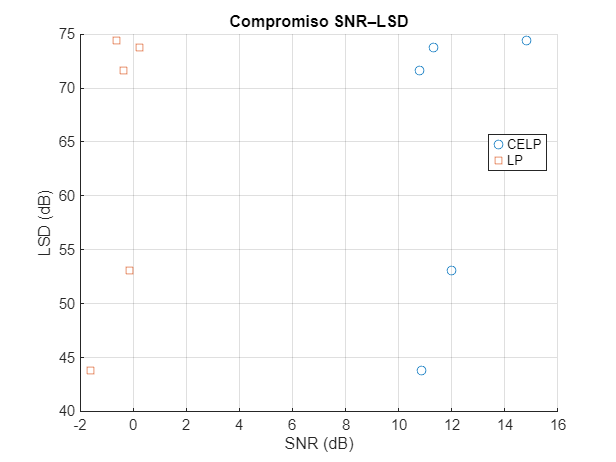


% (3) LSD vs SNR (dispersión)
figure; hold on; grid on;
idxC = T_detail.vocoder=="CELP"; idxL = T_detail.vocoder=="LP";
plot(T_detail.SNR_dB(idxC), T_detail.LSD_dB(idxC), 'o', 'DisplayName','CELP');
plot(T_detail.SNR_dB(idxL), T_detail.LSD_dB(idxL), 's', 'DisplayName','LP');
xlabel('SNR (dB)'); ylabel('LSD (dB)');
title('Compromiso SNR–LSD'); legend('Location','best');


%% ================== Helpers locales (auto-contenidos) ==================


function P0 = est_pitch_acf(xfrm, Fs, Prange)
% Estimación simple de pitch por autocorrelación en dominio temporal.
% Devuelve lag en muestras (entero). Si no fiable, NaN.
xmin = Prange(1); xmax = Prange(2);
x = xfrm(:) - mean(xfrm);
R = xcorr(x, xmax, 'coeff');
% R está centrada; los lags positivos van de 0..xmax al final del vector
Rpos = R(xmax+1 + (0:xmax));
% Evita el lag 0
Rpos(1) = -inf;
% Busca máximo en rango [xmin..xmax]
[Rmax, idx] = max(Rpos(xmin:xmax));
if isfinite(Rmax) && Rmax > 0.3
    P0 = xmin + idx - 1;
else
    P0 = NaN;
end
end

function e = pulse_train(N, P0)
% Tren de impulsos de periodo P0 (lag en muestras, entero)
e = zeros(N,1);
if ~isfinite(P0) || P0<=0, return; end
pos = 1:round(P0):N;
e(pos) = 1;
end
